# 案例：在指定区域内产生既不相交也不相切的随机圆

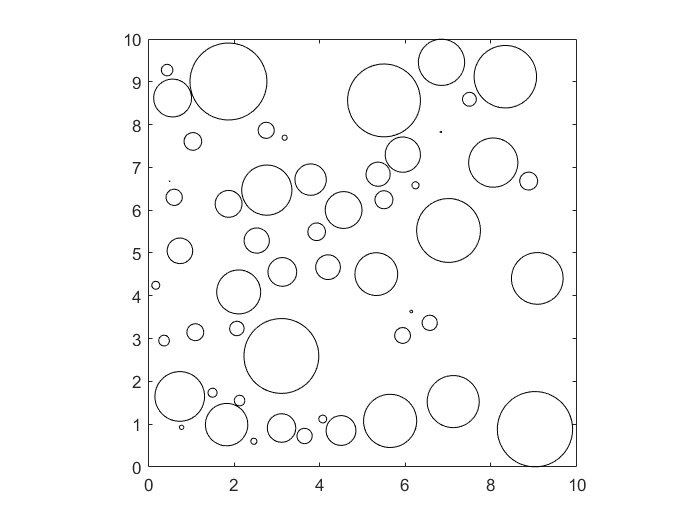

clear;clc;close all;
% 限定范围
width = 10;  
height = 10;
% 最多产生的圆的个数
circleNumber = 100;   
% 记录每个圆的横坐标、纵坐标、半径
paras = zeros(circleNumber, 3);  
num = 0;
hold on
while num < circleNumber
    num = num + 1;    
    % 圆半径小于1或者设定为固定值
    r = rand; 
    % 在范围内随机坐标
    xPos = rand*(width-2*r) + r;  
    yPos = rand*(height-2*r) + r;
    % 记录坐标、半径
    paras(num,:) = [xPos, yPos, r];
    % 判断每个圆的位置是否不相切、不相交
    if num > 1
        % 新产生的圆和之前产生的所有圆计算距离        
        xs = paras(1:num - 1, 1);
        ys = paras(1:num - 1, 2);
        rs = paras(1:num - 1, 3);
        dist1 = sqrt((xPos - xs).^2 + (yPos - ys).^2);
        dist2 = abs(r + rs);
        % 如果相离则绘制当前产生的圆，否则就重新生成一个圆
        if all(dist1 > dist2)
            rectangle('Position', [xPos-r, yPos-r, 2*r, 2*r], 'Curvature', [1 1]);
            axis equal
        else
            r = rand; 
            xPos = rand*(width-2*r) + r;  
            yPos = rand*(height-2*r) + r;
            paras(num,:) = [xPos,yPos,r];
            % 防止死循环
            temp = 0;
            maxTry = 100;
            while any(dist1 <= dist2) && temp < maxTry
                temp = temp + 1;
                dist1 = sqrt((xPos - xs).^2 + (yPos - ys).^2);
                dist2 = abs(r + rs);
            end
            if all(dist1 > dist2)
                rectangle('Position', [xPos-r, yPos-r, 2*r, 2*r], 'Curvature', [1 1]);
                axis equal
            end
        end      
    end
end
axis([0 width 0 height])
box on
hold off